downs = grabFromFilter('Downs');
ups = grabFromFilter('Ups');

upVals = zeros(size(ups, 1), 3);
downVals = zeros(size(downs, 1), 3);

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'; 'Moving_Grating_Direction'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'SP10'; 'Extracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %No Rig Mandates

upResiduals = zeros(size(ups, 1), 8);
downResiduals = zeros(size(downs, 1), 8);

%grab data for up cells, fit curve, and calculate error
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    
    [params, ~, ~] = sinewaveFit(orientations, spikes);
    upResiduals(i, :) = (spikes - (params(1).*(sin(2*pi*orientations./360 + params(2))) + params(3)))./mean(spikes); %normalize based on mean spike rate b/c more active cells will have higher raw residuals
    upVals(i, :) = params';
    close all
end

%grab data for down cells, fit curve, and calculate error
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    
    [params, ~, ~] = sinewaveFit(orientations, spikes);
    downResiduals(i, :) = (spikes - (params(1).*(sin(2*pi*orientations./360 + params(2))) + params(3)))./mean(spikes);
    downVals(i, :) = params';
    close all
end



## Compare Parameter by parameter

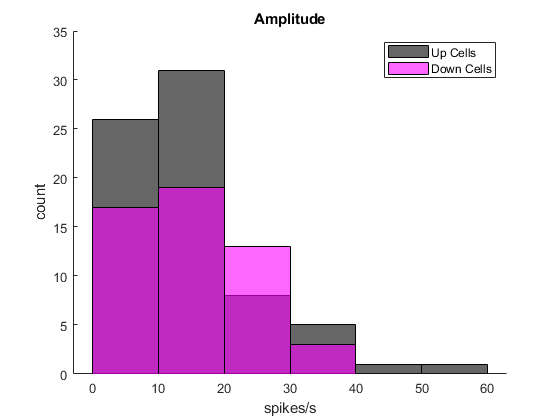

%parameter 1: amplitude (amplitude is often negative to compensate for
%phase shift)
figure
title('Amplitude')
hold on
histogram(abs(upVals(:, 1)), 'FaceColor', 'black')
histogram(abs(downVals(:, 1)), 'FaceColor', 'magenta', 'FaceAlpha', 0.6)
legend('Up Cells', 'Down Cells')
xlabel('spikes/s')
ylabel('count')

disp(['p = ' num2str(ranksum(abs(upVals(:, 1)), abs(downVals(:, 1))))])

p = 0.24314


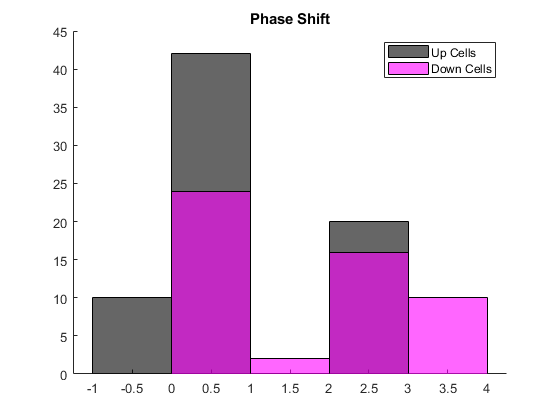

figure
title('Phase Shift')
hold on
histogram(upVals(:, 2), 'FaceColor', 'black')
histogram(downVals(:, 2), 'FaceColor', 'magenta', 'FaceAlpha', 0.6)
legend('Up Cells', 'Down Cells')

disp(['p = ' num2str(ranksum(upVals(:, 2), downVals(:, 2)))])

p = 1.8192e-06


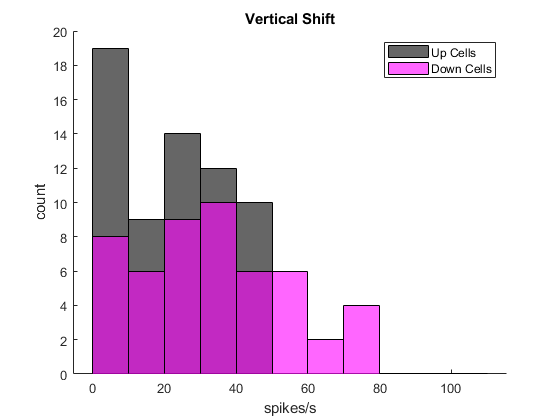

figure
title('Vertical Shift')
hold on
histogram(upVals(:, 3), 'BinEdges', 0:10:max(upVals(:, 3)), 'FaceColor', 'black')
histogram(downVals(:, 3),'BinEdges', 0:10:max(downVals(:, 3)), 'FaceColor', 'magenta', 'FaceAlpha', 0.6)
legend('Up Cells', 'Down Cells')
xlabel('spikes/s')
ylabel('count')

disp(['p = ' num2str(ranksum(upVals(:, 3), downVals(:, 3)))])

p = 0.031193


## Compare residuals

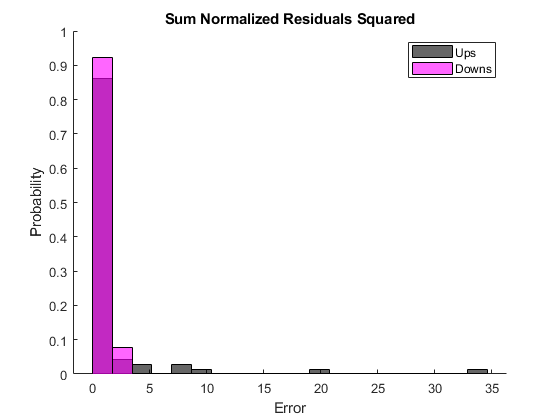

upSumResidualsSquared = sum((upResiduals.^2), 2);
downSumResidualsSquared = sum(downResiduals.^2, 2);

[~, edgs] = discretize([upSumResidualsSquared; downSumResidualsSquared], 20);
figure
title('Sum Normalized Residuals Squared')
hold on
histogram(upSumResidualsSquared, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization', 'probability')
histogram(downSumResidualsSquared, 'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability')
legend('Ups', 'Downs')
xlabel('Error')
ylabel('Probability')

disp(['p = ' num2str(ranksum(upSumResidualsSquared, downSumResidualsSquared))])

p = 0.35017
